clear;close;clc;
% Same algorithm as boot.xlm, 
% but starts a script based system instead of Simulink Simulation

% Working directory
currentFolder="C:\Users\Administrator\Documents\RNNMPC";
cd(currentFolder)

% Determine where your m-file's folder is.s
currentFolder = pwd;

% Add that folder plus all subfolders to the path.
addpath(genpath(currentFolder));


% Construct a drivingScenario object.

% time stamps
T0=0;
Ts=0.1;
Te=30;
T=[T0:Ts:Te];

scenario = drivingScenario('SampleTime',Ts, 'StopTime',Te);

% Add all road segments
roadCenters = [18 -400 0;
    24.0649580066019 -517.193260613925 0;
    47.9750875785322 -536.235754667303 0;
    76.6624478766495 -523.86324919821 0;
    92.9207165458355 -401.033127036538 0;
    170.3867343289 -327.239977647937 0;
    175.638329011851 -310.583707423304 0;
    220.589417862495 -94.9286389485818 0;
    369.284691020735 35.5160409637706 0;
    376.928401491428 50.2749423777918 0;
    383.621758729161 83.5987651522238 0;
    323.857116789485 188.318052659596 0;
    249.272937073171 204.507402924895 0;
    203.848829308523 146.426557679798 0;
    230.150558692309 53.6019700547394 0;
    220.105120680016 -1.61571858138137 0;
    173.254881446187 -44.9376574339232 0;
    123.527790307155 -52.5609411441475 0;
    72.6630287615676 -20.1134079563903 0;
    77.0904329809449 17.0164034834116 0;
    87.5307589250409 45.4684566610883 0;
    73.1034401434289 80.1461122044347 0;
    72.0105163889276 107.311078655012 0;
    103.922000574666 145.006530880687 0;
    109.666332907755 164.991806883824 0;
    94.8451425487286 229.264591330367 0;
    154.132464853073 315.419707487138 0;
    195.24584480359 312.090617826022 0;
    244.971069253516 276.858486287906 0;
    294.696108072602 288.288674570601 0;
    310.951091560049 318.749605568912 0;
    301.380240074167 351.129928799823 0;
    287.517385640031 363.025521607973 0;
    148.388951278336 439.670587819864 0;
    108.235046546122 446.328932608309 0;
    27.9085385256614 406.825415466225 0;
    5.44255812286789 367.310152431137 0;
    1.61556779338585 337.326683360315 0;
    15.7973364726795 -301.038813069664 0;
    18 -400 0];
marking = [laneMarking('Solid', 'Color', [0.98 0.86 0.36])
    laneMarking('Solid', 'Color', [0.98 0.86 0.36])];
laneSpecification = lanespec(1, ...
    'Marking', marking, ...
    'width',10, ...
    'type',laneType('Driving'));

road = road(scenario, roadCenters, 'Lanes', laneSpecification, 'Name', 'NCCAR');

clear marking laneSpecification

% Add the ego vehicle
egoVehicle = vehicle(scenario, ...
    'ClassID', 1, ...
    'Position', [0 0 0], ...
    'Mesh', driving.scenario.carMesh, ...
    'Name', 'EgoCar');

waypoints = [0 0 0;
    48.1 -536.4 0;
    383.6 83.7 0;
    249.3 204.5 0;
    230.6 54 0;
    123.5 -52.6 0;
    72.7 -20 0;
    154.3 315.9 0;
    295.8 287.7 0;
    109.6 447.6 0;
    1.7 338.4 0;
    1 0 0];
speed=ones(size(waypoints,1),1);
yaw =  [-95;NaN;NaN;NaN;NaN;NaN;NaN;NaN;NaN;NaN;NaN;NaN];
smoothTrajectory(egoVehicle, waypoints, speed, 'Yaw', yaw);

egoVehicle.Yaw=-95;

% Assign into each sensor the physical and radar profiles for all actors
profiles = actorProfiles(scenario);
sensors{1} = insSensor('TimeInput', true);
sensors{2} = visionDetectionGenerator('SensorIndex', 2, ...
    'SensorLocation', [1.5 0], ...
    'HasNoise', false, ...
    'DetectionProbability', 1, ...
    'FalsePositivesPerImage', 0, ...
    'DetectorOutput', 'Lanes only', ...
    'Intrinsics', cameraIntrinsics([554.256 311.769145362398],[960 540],[1080 1920]), ...
    'ActorProfiles', profiles);
numSensors = 2;

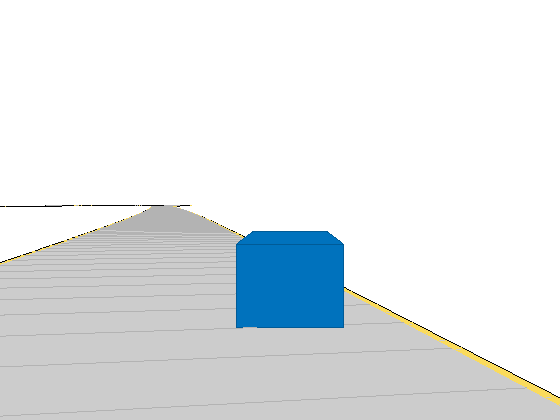

Error using driving.scenario.DefaultScenario/advance
The simulation is not running.  Call restart to start over.

Error in drivingScenario/advance (line 42)
running = advance(obj.Scenario);

% % Visualize the scenario
% figure('Name','Scenario Plot')
% plot(scenario)

% Visualize Third-person View
figure('Name','TPV Plot')
chasePlot(egoVehicle)

% % Simulation
% birdseye=birdsEyePlot('XLim',[-20 30],'YLim',[-15 15]);
% olPlotter = outlinePlotter(birdseye);
% lblPlotter = laneBoundaryPlotter(birdseye,'Color','r','LineStyle','-');
% lbrPlotter = laneBoundaryPlotter(birdseye,'Color','g','LineStyle','-');
% rbsEdgePlotter = laneBoundaryPlotter(birdseye,'Color','k','LineStyle','--');
% legend('off');


for t=T

        egoVehicle.Position=[0,0,0];
        egoVehicle.Velocity=[0,0,0];
        egoVehicle.Yaw=-90;
        
        egoState=state(egoVehicle);

        % rbs = roadBoundaries(egoVehicle);
        % [position,yaw,length,width,originOffset,color] = targetOutlines(egoVehicle);
        % lb = laneBoundaries(egoVehicle,'XDistance',0:5:30,'LocationType','Center', ...
        %     'AllBoundaries',false);
        % plotLaneBoundary(rbsEdgePlotter,rbs)
        % plotLaneBoundary(lblPlotter,{lb(1).Coordinates})
        % plotLaneBoundary(lbrPlotter,{lb(2).Coordinates})
        % plotOutline(olPlotter,position,yaw,length,width, ...
        %     'OriginOffset',originOffset,'Color',color)

        
        % chasePlot(egoVehicle)
        advance(scenario);
end